## `PS1`

`刘沛雨 2100012289 信息科学技术学院`

`本次作业由个人独立完成，与小组成员进行了讨论。`

### `Lab Manual`

`﻿``Exercise 6.1`

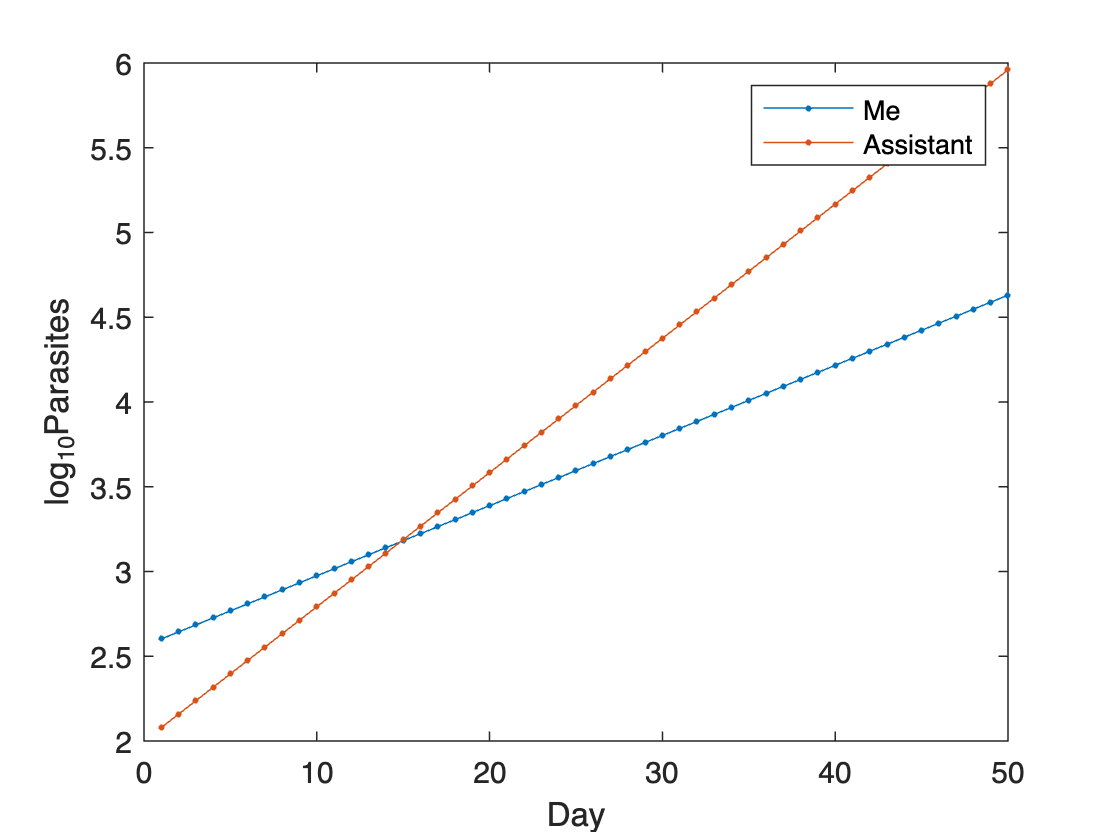

time_range =50;
time_vector = 1:time_range;
parasites = zeros(2, time_range);
parasites(1, 1) = 400; % me
parasites(2, 1) = 120; % assistant
me_rate = 0.1;
assistant_rate = 0.2;
for t = 2: time_range
    parasites(1, t) = parasites(1, t - 1) * (1 + me_rate);
    parasites(2, t) = parasites(2, t - 1) * (1 + assistant_rate);
end
% plot
for i = 1:size(parasites, 1)
    plot(time_vector, log10(parasites(i, :)), ' - .');
    hold on
end
legend(["Me","Assistant"])
xlabel("Day")
ylabel("log_{10}Parasites")
hold off

`﻿``Exercise 9.3`

A=ones(2,2); 
S=0.5*eye(2); 
Z=ones(2,2); 
B=rmatrix(A,S,Z); % 函数定义见末尾部分
B

B =     1.5000    1.0000
    1.0000    1.5000


### `Fibonacci sequence`


$$f_{n+2} =f_{n+1} +f_n ,\;\;f_1 =1,\;f_2 =1$$


nmax = 100;
f = zeros(1, nmax);
r = zeros(1,nmax - 1);
f(1) = 1;
f(2) = 1;
for n = 1: nmax - 2
    f(n + 2) = f(n + 1) + f(n);
    r(n) = f(n+1) / f(n);
end
r(nmax - 1) = f(nmax) / f(nmax - 1); % 维护边界
% print f(1:100)
fprintf("The first 100 elements in the Fibonacci sequence:\n");

The first 100 elements in the Fibonacci sequence:


for i = 1: 100
    fprintf("%d ", f(1, i));
end

1 1 2 3 5 8 13 21 34 55 89 144 233 377 610 987 1597 2584 4181 6765 10946 17711 28657 46368 75025 121393 196418 317811 514229 832040 1346269 2178309 3524578 5702887 9227465 14930352 24157817 39088169 63245986 102334155 165580141 267914296 433494437 701408733 1134903170 1836311903 2971215073 4807526976 7778742049 12586269025 20365011074 32951280099 53316291173 86267571272 139583862445 225851433717 365435296162 591286729879 956722026041 1548008755920 2504730781961 4052739537881 6557470319842 10610209857723 17167680177565 27777890035288 44945570212853 72723460248141 117669030460994 190392490709135 308061521170129 498454011879264 806515533049393 1304969544928657 2111485077978050 3416454622906707 5527939700884757 8944394323791464 14472334024676220 23416728348467684 37889062373143904 61305790721611584 99194853094755488 160500643816367072 259695496911122560 420196140727489664 679891637638612224 1100087778366101888 1779979416004713984 2880067194370816000 4660046610375530496 7540113804746346496 

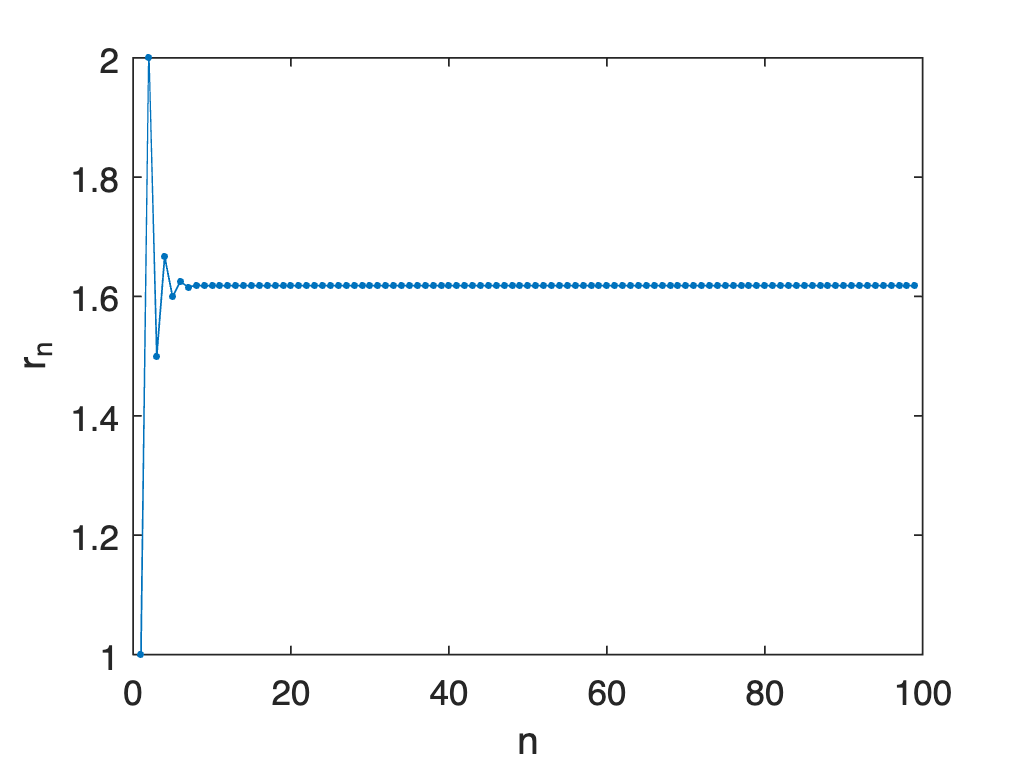

% plot r
plot(1:nmax - 1, r, ' - .')
xlabel("n")
ylabel("r_n")

`从图中可以观察到，当`$n$`充分大时，`$r_n \approx 1\ldotp 618$`，原因如下：`

`由题目定义可知：`$\vec{x_n } =\left\lbrack \begin{array}{cc}
f_{n+1}  & f_n 
\end{array}\right\rbrack ,\;\vec{x_{n+1} } =\left\lbrack \begin{array}{cc}
f_{n+2}  & f_{n+1} 
\end{array}\right\rbrack$`.`

`注意到`$\;\vec{x_{n+1} } =\vec{x_n } \times \left\lbrack \begin{array}{cc}
1 & 1\\
1 & 0
\end{array}\right\rbrack$`，`

`因此令`$A=\left\lbrack \begin{array}{cc}
1 & 1\\
1 & 0
\end{array}\right\rbrack$`，则有`$\vec{x_n } =\left\lbrack \begin{array}{cc}
1 & 1
\end{array}\right\rbrack \times A^{n-1} ,n\in \left\lbrace 1,2,3,\ldotp \ldotp \ldotp \right\rbrace$`，下面求`$A^{n-1} \ldotp$

`首先求`$A$`的特征值与特征向量:`

`求得： `$\begin{array}{l}
\lambda_1 =\frac{1-\sqrt{5}}{2},\vec{v_1 } =\left\lbrack \begin{array}{c}
1\\
-\frac{\sqrt{5}+1}{2}
\end{array}\right\rbrack \\
\lambda_2 =\frac{1+\sqrt{5}}{2},\vec{v_2 } =\left\lbrack \begin{array}{c}
1\\
\frac{\sqrt{5}-1}{2}
\end{array}\right\rbrack 
\end{array}$`，从而有`$A=V\times D\times V^{-1}$`，其中`$D=\left\lbrack \begin{array}{cc}
\lambda_1  & 0\\
0 & \lambda_2 
\end{array}\right\rbrack ,V=\left\lbrack \begin{array}{cc}
\vec{v_1 }  & \vec{v_2 } 
\end{array}\right\rbrack ,V^{-1} =\left\lbrack \begin{array}{cc}
\frac{5-\sqrt{5}}{10} & -\frac{\sqrt{5}}{5}\\
\frac{5+\sqrt{5}}{10} & \frac{\sqrt{5}}{5}
\end{array}\right\rbrack$`.`

`故`$A^{n-1} =V\times D^{n-1} \times V^{-1}$`,`

    $\vec{x_n } =\left\lbrack \begin{array}{cc}
1 & 1
\end{array}\right\rbrack$$\times$$V\times D^{n-1} \times V^{-1}$`,`

    $f_n =\vec{x_n } \left(1,2\right)=\frac{\sqrt{5}}{5}\left(\frac{\sqrt{5}+1}{2}\lambda_2^{n-1} +\frac{\sqrt{5}-1}{2}\lambda_1^{n-1} \right)=\frac{\sqrt{5}}{5}\left({\left(\frac{1+\sqrt{5}}{2}\right)}^n -{\left(\frac{1-\sqrt{5}}{2}\right)}^n \right)$`.`

`由`$r_n =\frac{f_{n+1} }{f_n }$`知：`$r_n =\frac{\lambda_2^{n+1} -\lambda_1^{n+1} }{\lambda_2^n -\lambda_1^n }=\frac{\lambda_2 -\lambda_1 {\left(\frac{\lambda_1 }{\lambda_2 }\right)}^n }{1-{\left(\frac{\lambda_1 }{\lambda_2 }\right)}^n }\left(|\lambda_2 |>|\lambda_1 |\right)\ldotp$

`因此，`$\lim_{n\to \infty } r_n =$$\lambda_2 \approx 1\ldotp 618\ldotp$

### `EG Practice`

`Exercise 2.6`

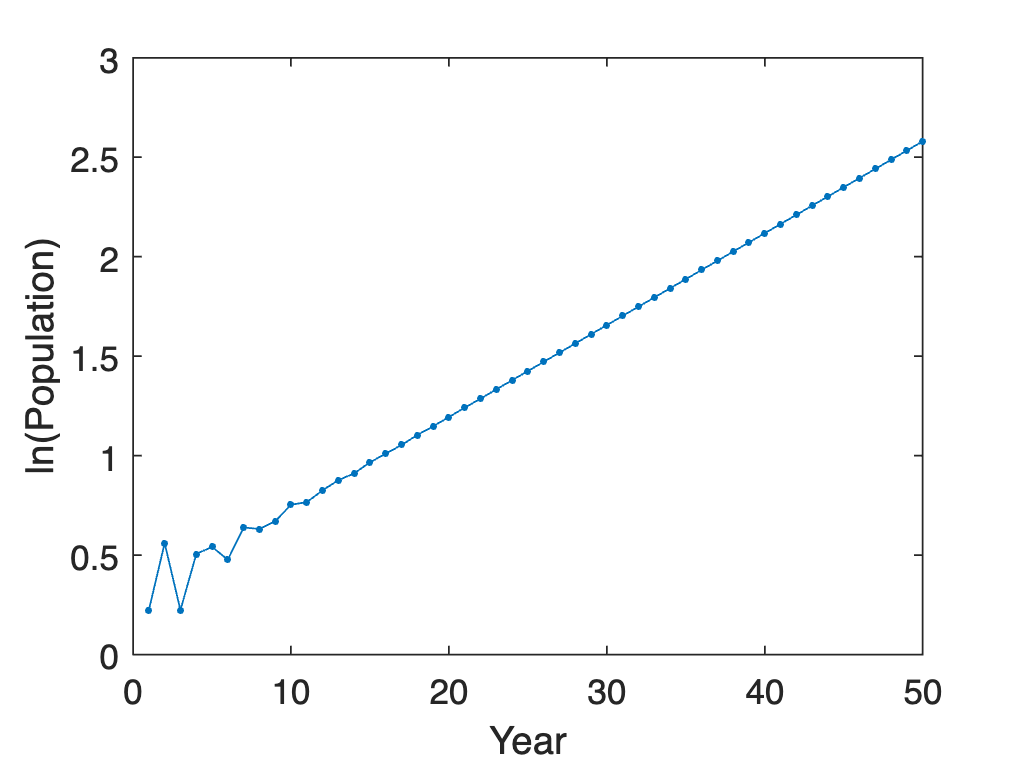

L = [0 1 5
    0.5 0 0
    0 0.25 0];
time_range = 50;
N = zeros(1, time_range);
fraction = zeros(3, time_range);
n = zeros(3,1); % 初始化n0
n(2,1) = 1; 
for t = 1: time_range
    n = L * n;
    N(t) = sum(n);
    fraction(:,t) = n / N(t); % 计算各年龄植物占比
end
% plot N
plot(1:time_range, log(N(1, :)), ' - .')
xlabel("Year")
ylabel("ln(Population)")

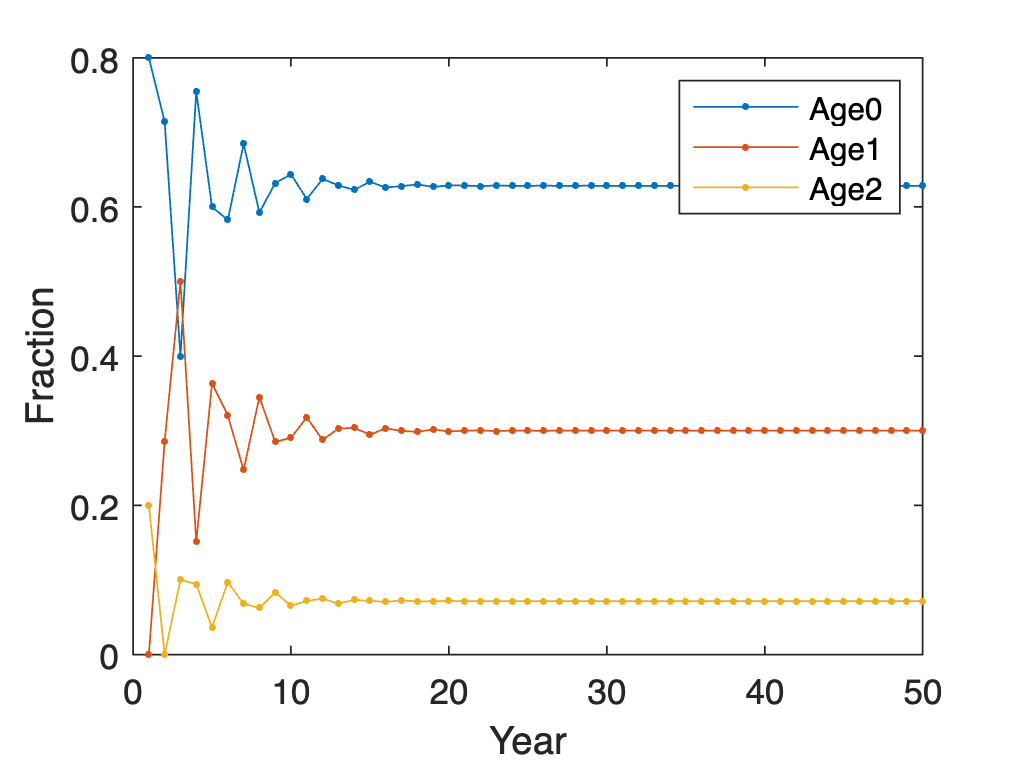

% plot fraction
for i = 1:size(fraction, 1)
    plot(1: time_range, fraction(i, :), ' - .');
    hold on
end
legend(["Age0", "Age1", "Age2"]);
xlabel("Year");
ylabel("Fraction");
hold off

`可以注意到，在较长的时间尺度下，种群数量呈指数增长，而种群中各个年龄的个体数量比例趋于稳定`

`Exercise 2.7`

`Euler-Lotka方程：`$\sum_{a=0}^A \lambda^{-\left(a+1\right)} I_a f_a =1\ldotp$

`在本问题中：`$A=2$`，方程可展开为`$\lambda^{-1} I_0 f_0 +\lambda^{-2} I_1 f_1 +\lambda^{-3} I_2 f_2 =1\ldotp$

`其中 `$\begin{array}{l}
I_0 =1,I_1 =p_0 =0\ldotp 5,I_2 =p_0 p_1 =0\ldotp 125\\
f_0 =0,f_1 =1,f_2 =5
\end{array}$`.`

`故方程可化简为`${0\ldotp 5\lambda }^{-2} +{0\ldotp 625\lambda }^{-3} =1\ldotp$

`求方程的数值解：`

fun = @(lambda) 0.5 * lambda.^(-2) + 0.625 * lambda.^(-3) - 1;
[root, fval, exitflag, output] = fzero(fun, 1)

root = 1.0473

fval = 0

exitflag = 1

output = struct with fields:
    intervaliterations: 3
            iterations: 5
             funcCount: 12
             algorithm: 'bisection, interpolation'
               message: 'Zero found in the interval [0.943431, 1.05657]'


`方程的数值解为`$\lambda =1\ldotp 0473\ldotp$

`下面求模拟得到的 N(t) 的种群增长率：`

ft = polyfit(1: time_range, log(N), 1)

ft =     0.0463    0.2677


lambda_simu = exp(ft(1, 1))

lambda_simu = 1.0473

`方程数值解与模拟得到的增长率一致。`

`Exercise 2.11`

`取`$L_1 =\left\lbrack \begin{array}{cccc}
1 & 2 & 3 & 4\\
0\ldotp 1 & 0 & 0 & 0\\
0 & 0\ldotp 2 & 0 & 0\\
0 & 0 & 0\ldotp 3 & 0
\end{array}\right\rbrack ,L_2 =\left\lbrack \begin{array}{cccc}
1 & 0 & 3 & 0\\
0\ldotp 1 & 0 & 0 & 0\\
0 & 0\ldotp 2 & 0 & 0\\
0 & 0 & 0\ldotp 3 & 0
\end{array}\right\rbrack \ldotp$


$$n=4,n^2 -2n+2=10\ldotp$$


`验证如下：`

I = [1 0 0 0 
     0 1 0 0
     0 0 1 0
     0 0 0 1];
L1 = I;
L2 = I;
for i = 1: 10
    L1 = L1 * [1 2 3 4
              0.1 0 0 0
              0 0.2 0 0
              0 0 0.3 0];
    fprintf("Minimum of L1^%d: %d\n", i, min(L1(:)));
    L2 = L2 * [1 0 3 0
              0.1 0 0 0
              0 0.2 0 0
              0 0 0.3 0];
    fprintf("Minimum of L2^%d: %d\n", i, min(L2(:)));
end

Minimum of L1^1: 0


Minimum of L2^1: 0


Minimum of L1^2: 0


Minimum of L2^2: 0


Minimum of L1^3: 0


Minimum of L2^3: 0


Minimum of L1^4: 6.000000e-03


Minimum of L2^4: 0


Minimum of L1^5: 7.200000e-03


Minimum of L2^5: 0


Minimum of L1^6: 8.760000e-03


Minimum of L2^6: 0


Minimum of L1^7: 1.070400e-02


Minimum of L2^7: 0


Minimum of L1^8: 1.303200e-02


Minimum of L2^8: 0


Minimum of L1^9: 1.587120e-02


Minimum of L2^9: 0


Minimum of L1^10: 1.933008e-02


Minimum of L2^10: 0


`对L2进行模拟，结果表明种群数量呈指数增长：`

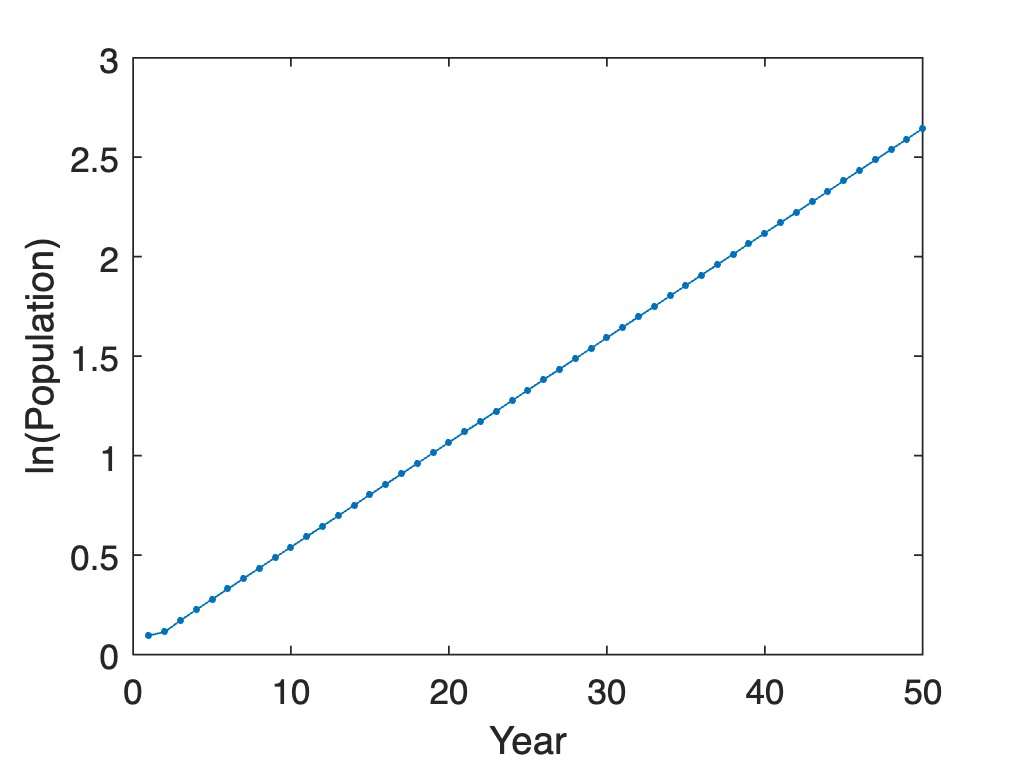

L2 = [1 0 3 0
      0.1 0 0 0
      0 0.2 0 0 
      0 0 0.3 0];
time_range = 50;
N = zeros(1, time_range);
n = zeros(4,1); % 初始化n0
fraction = zeros(4, time_range);
n(1,1) = 1; 
for t = 1: time_range
    n = L2 * n;
    N(t) = sum(n);
    fraction(:,t) = n / N(t);
end
% plot N
plot(1:time_range, log(N(1, :)), '- .');
xlabel("Year");
ylabel("ln(Population)");

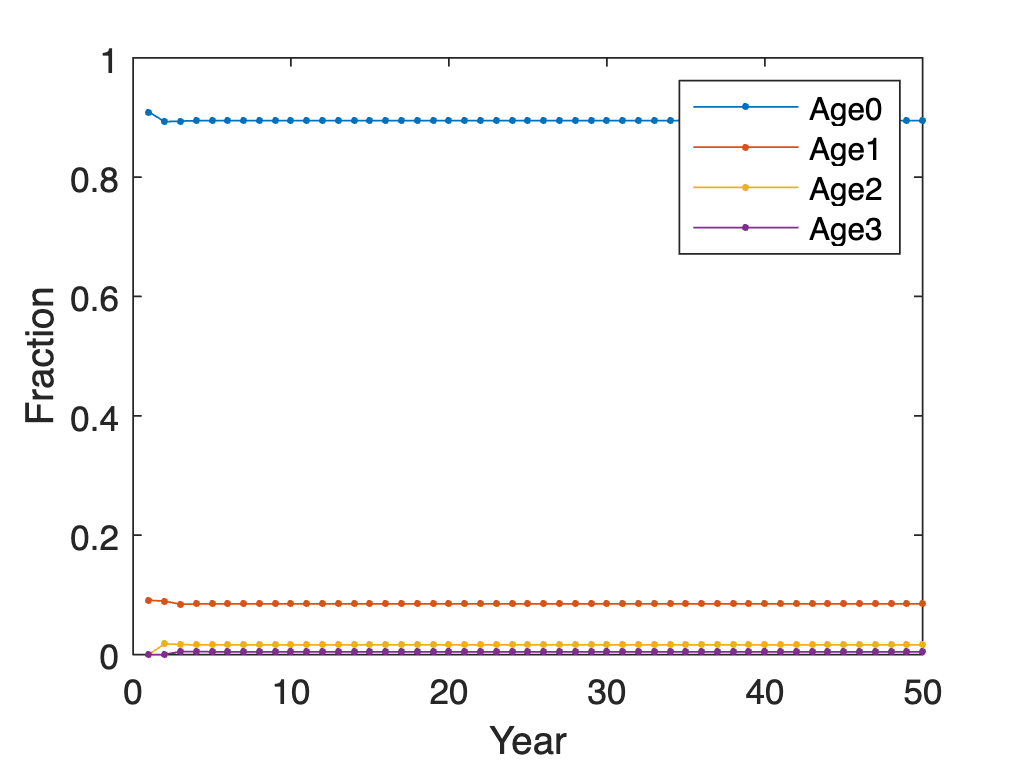

% plot fraction
for i = 1:size(fraction, 1)
    plot(1: time_range, fraction(i, :), ' - .');
    hold on
end
legend(["Age0", "Age1", "Age2", "Age3"]);
xlabel("Year");
ylabel("Fraction");
hold off

`Exercise 2.13`


$$A=\left\lbrack \begin{array}{cccc}
0 & 0\ldotp 0043 & 0\ldotp 1132 & 0\\
0\ldotp 9775 & 0\ldotp 9111 & 0 & 0\\
0 & 0\ldotp 0736 & 0\ldotp 9534 & 0\\
0 & 0 & 0\ldotp 0452 & 0\ldotp 9804
\end{array}\right\rbrack$$


A = [0 0.0043 0.1132 0
    0.9775 0.9111 0 0
    0 0.0736 0.9534 0
    0 0 0.0452 0.9804];
[V, D] = eig(A) % 求特征值和对应的特征向量

V =          0    0.0663   -0.0659    0.6788
         0    0.5672    0.8380   -0.7321
         0    0.5795   -0.5175    0.0568
    1.0000    0.5815    0.1600   -0.0026


D =     0.9804         0         0         0
         0    1.0254         0         0
         0         0    0.8342         0
         0         0         0    0.0048


dominant_lambda = D(2, 2)

dominant_lambda = 1.0254

w = V(:, 2) %dominant_lambda 对应的特征向量

w =     0.0663
    0.5672
    0.5795
    0.5815


`（a）主特征值`$\lambda =1\ldotp 0254$`，对应的特征向量为`$\vec{w} =\left\lbrack \begin{array}{c}
0\ldotp 0663\\
0\ldotp 5672\\
0\ldotp 5795\\
0\ldotp 5815
\end{array}\right\rbrack \ldotp$

`（b）`$x_0 =\left\lbrack \begin{array}{cccc}
10 & 60 & 110 & 70
\end{array}\right\rbrack \ldotp$

x = [10
    60
    110
    70];
time_range = 50;
N = zeros(1, time_range);
fraction = zeros(4, time_range);
lambda = zeros(1, time_range - 1);
for t = 1: time_range
    x = A * x;
    N(t) = sum(x);
    fraction(:,t) = x / N(t);
end
for t = 1: time_range - 1
    lambda(t) = N(t + 1) / N(t);
end

`（c）`

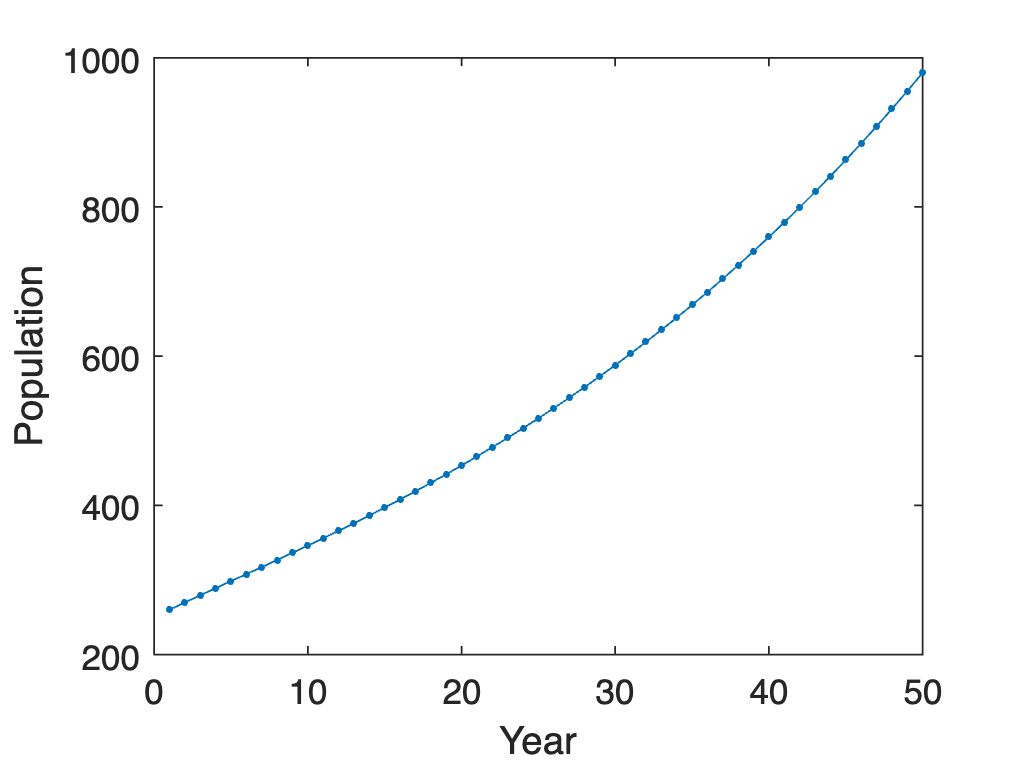

% plot N
plot(1:time_range, N(1, :), '- .');
xlabel("Year");
ylabel("Population");

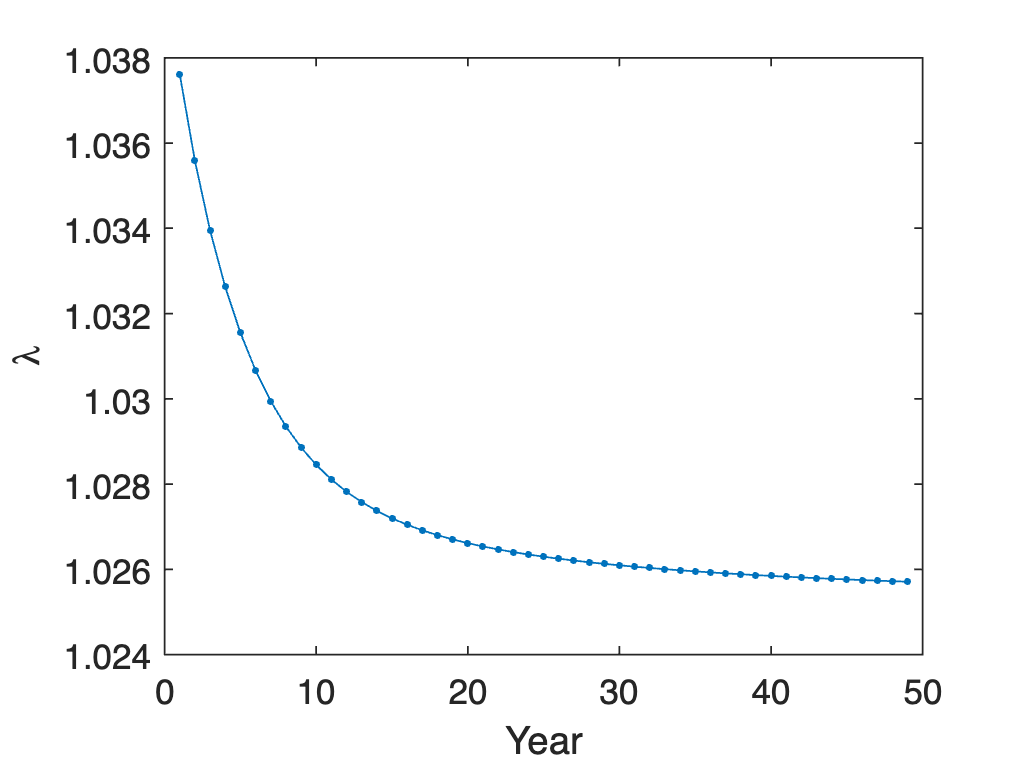

% plot lambda
plot(1:time_range - 1, lambda(1, :), '- .');
xlabel("Year");
ylabel("\lambda");

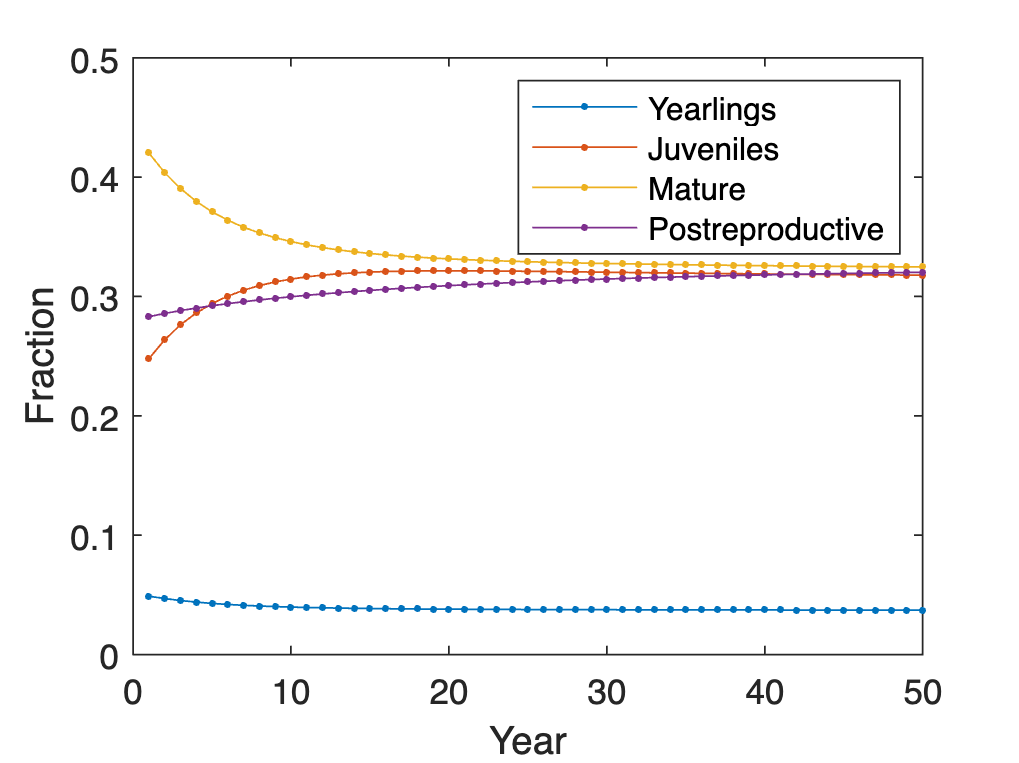

% plot fraction
for i = 1:size(fraction, 1)
    plot(1: time_range, fraction(i, :), '- .');
    hold on
end
% legend(["﻿Yearling" , "﻿Juveniles", "Mature", ﻿"Postreproductive"]);
legend(["Yearlings", "Juveniles", "Mature", "Postreproductive"]);
xlabel("Year");
ylabel("Fraction");
hold off

`种群结构随时间变化趋于稳定，种群数量大致呈指数增长。达到稳定时，Yearling个体在种群中占比较低，其他三个阶段个体在种群中占比接近，该结果与稳定分布`$\vec{w}$`一致；随着时间推移，种群数量年增长率逐渐放缓，以指数速度趋于主特征值`$\lambda$`，但从数量上看`$\lambda$`变化较慢。`

`Exercise 2.14`

`1.`$x_0 =\left\lbrack \begin{array}{cccc}
250 & 0 & 0 & 0
\end{array}\right\rbrack$

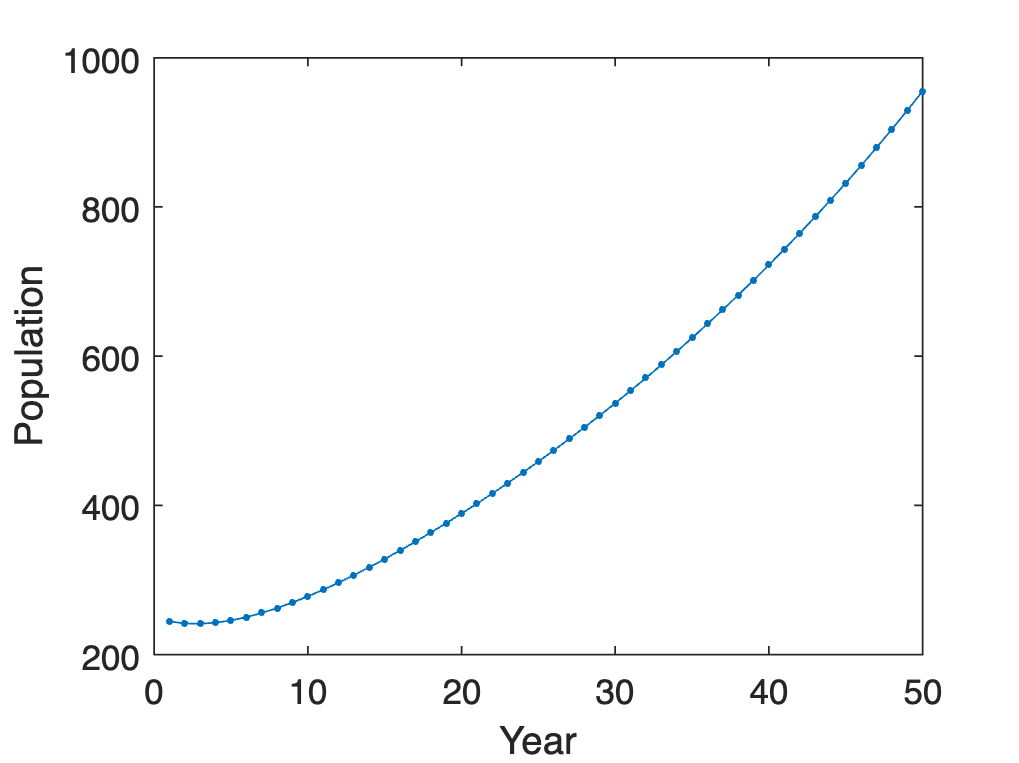

x = [250
    0
    0
    0];
time_range = 50;
N = zeros(1, time_range);
fraction = zeros(4, time_range);
lambda = zeros(1, time_range - 1);
for t = 1: time_range
    x = A * x;
    N(t) = sum(x);
    fraction(:,t) = x / N(t);
end
for t = 1: time_range - 1
    lambda(t) = N(t + 1) / N(t);
end
% plot N
plot(1:time_range, N(1, :), '- .');
xlabel("Year");
ylabel("Population");

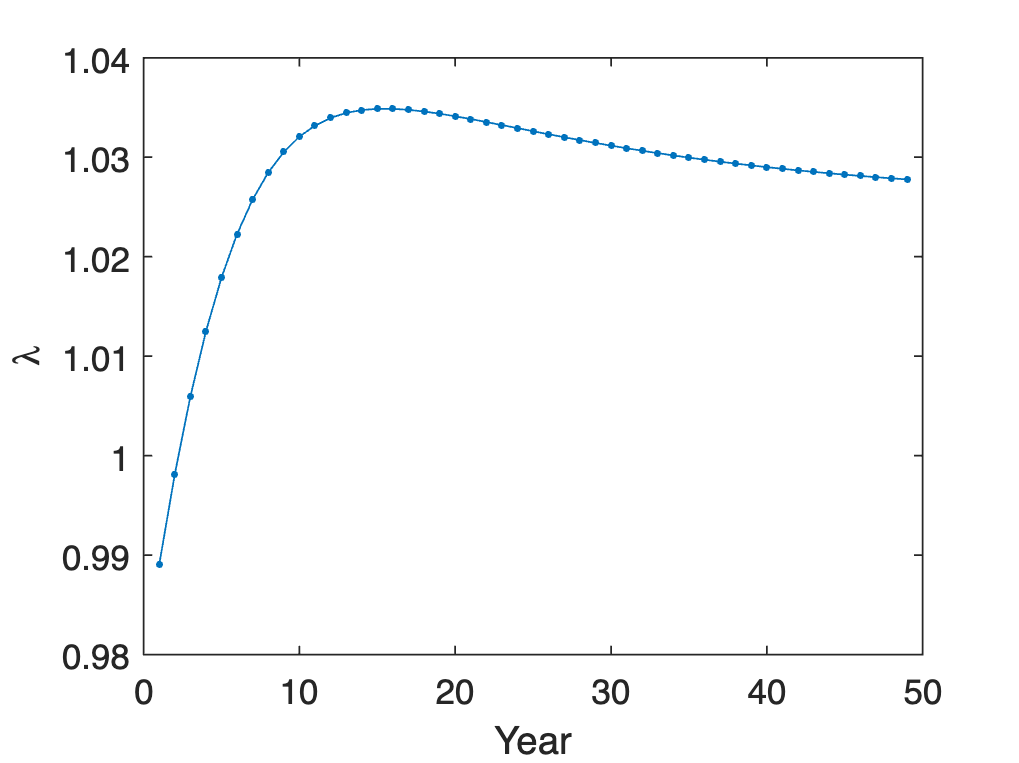

% plot lambda
plot(1:time_range - 1, lambda(1, :), '- .');
xlabel("Year");
ylabel("\lambda");

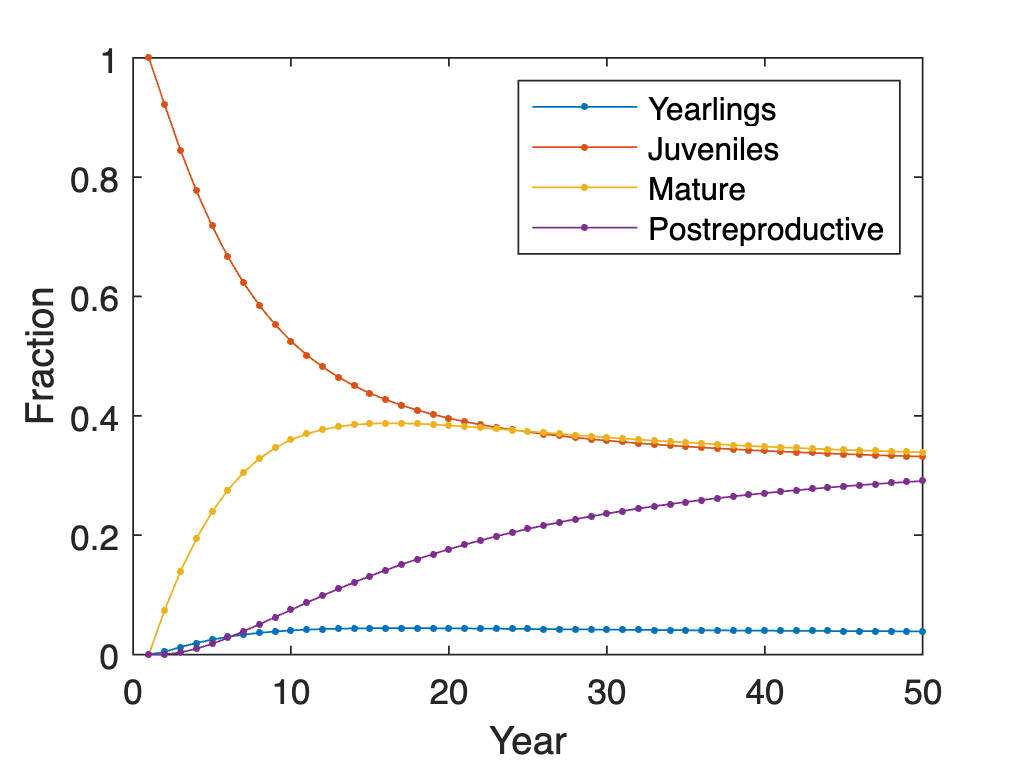

% plot fraction
for i = 1:size(fraction, 1)
    plot(1: time_range, fraction(i, :), '- .');
    hold on
end
legend(["Yearlings", "Juveniles", "Mature", "Postreproductive"]);
xlabel("Year");
ylabel("Fraction");
hold off

`2.`$x_0 =\left\lbrack \begin{array}{cccc}
0 & 250 & 0 & 0
\end{array}\right\rbrack$

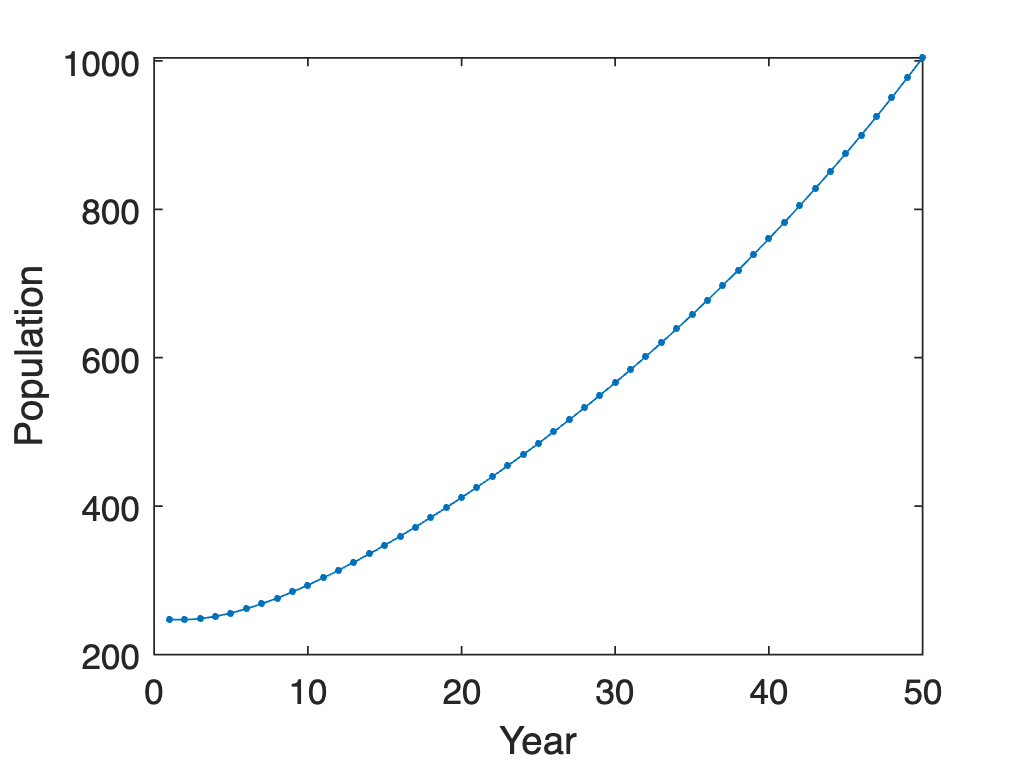

x = [0
    250
    0
    0];
time_range = 50;
N = zeros(1, time_range);
fraction = zeros(4, time_range);
lambda = zeros(1, time_range - 1);
for t = 1: time_range
    x = A * x;
    N(t) = sum(x);
    fraction(:,t) = x / N(t);
end
for t = 1: time_range - 1
    lambda(t) = N(t + 1) / N(t);
end
% plot N
plot(1:time_range, N(1, :), '- .');
xlabel("Year");
ylabel("Population");

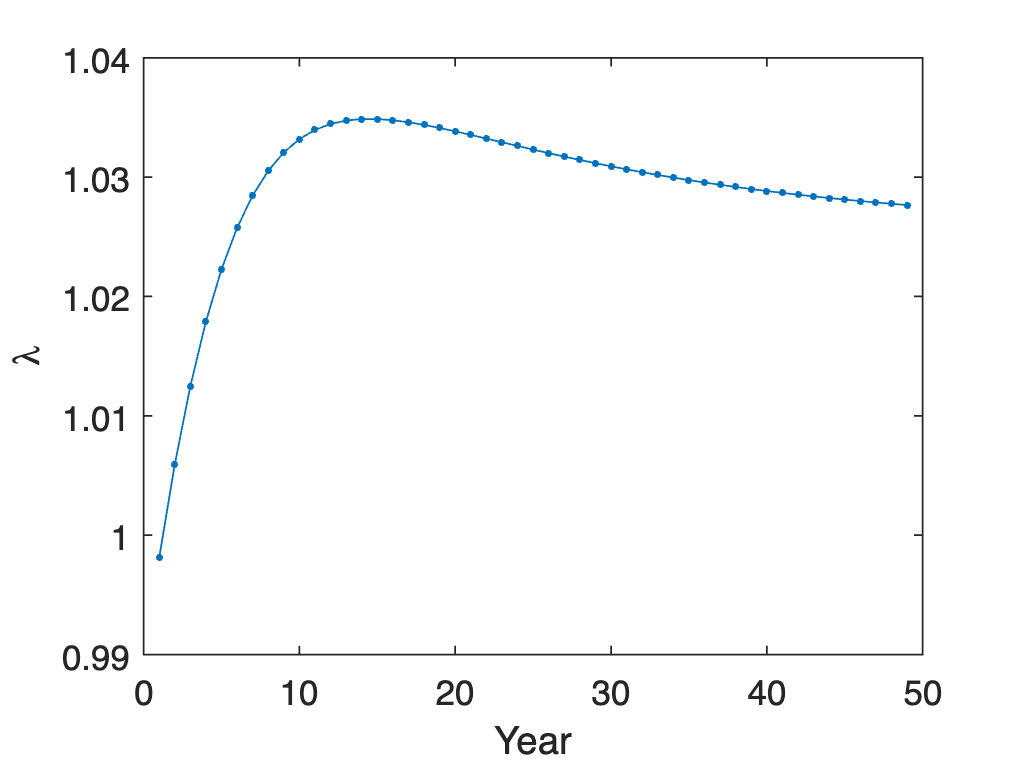

% plot lambda
plot(1:time_range - 1, lambda(1, :), '- .');
xlabel("Year");
ylabel("\lambda");

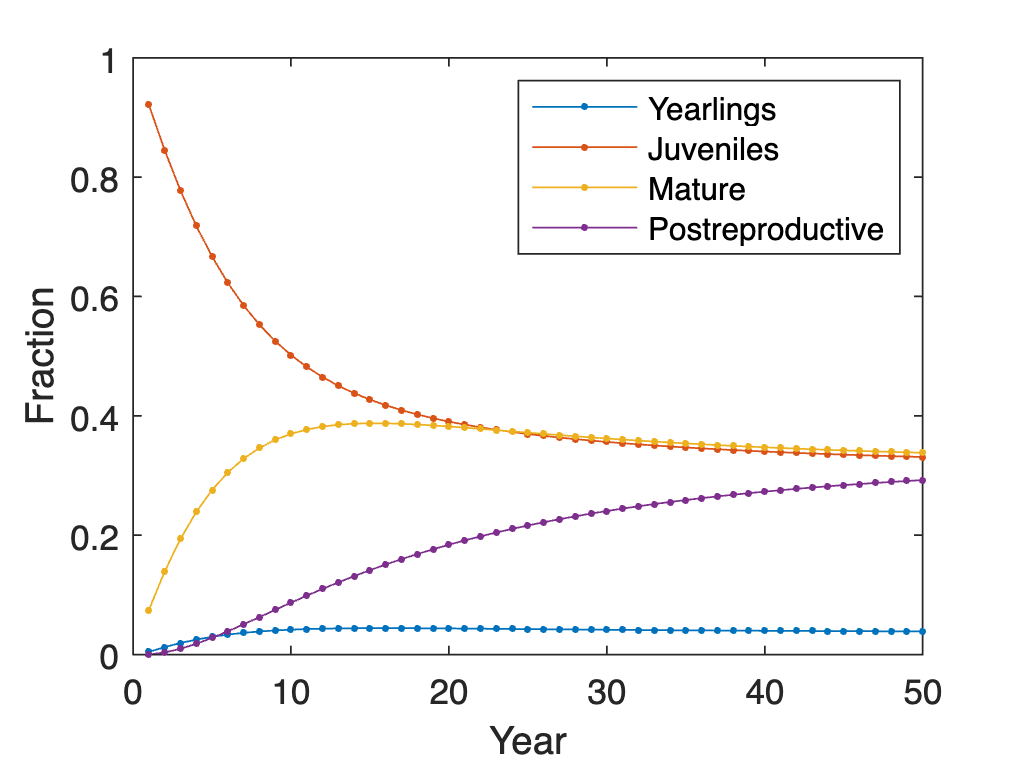

% plot fraction
for i = 1:size(fraction, 1)
    plot(1: time_range, fraction(i, :), '- .');
    hold on
end
legend(["Yearlings", "Juveniles", "Mature", "Postreproductive"]);
xlabel("Year");
ylabel("Fraction");
hold off

`3.`$x_0 =\left\lbrack \begin{array}{cccc}
0 & 0 & 250 & 0
\end{array}\right\rbrack$

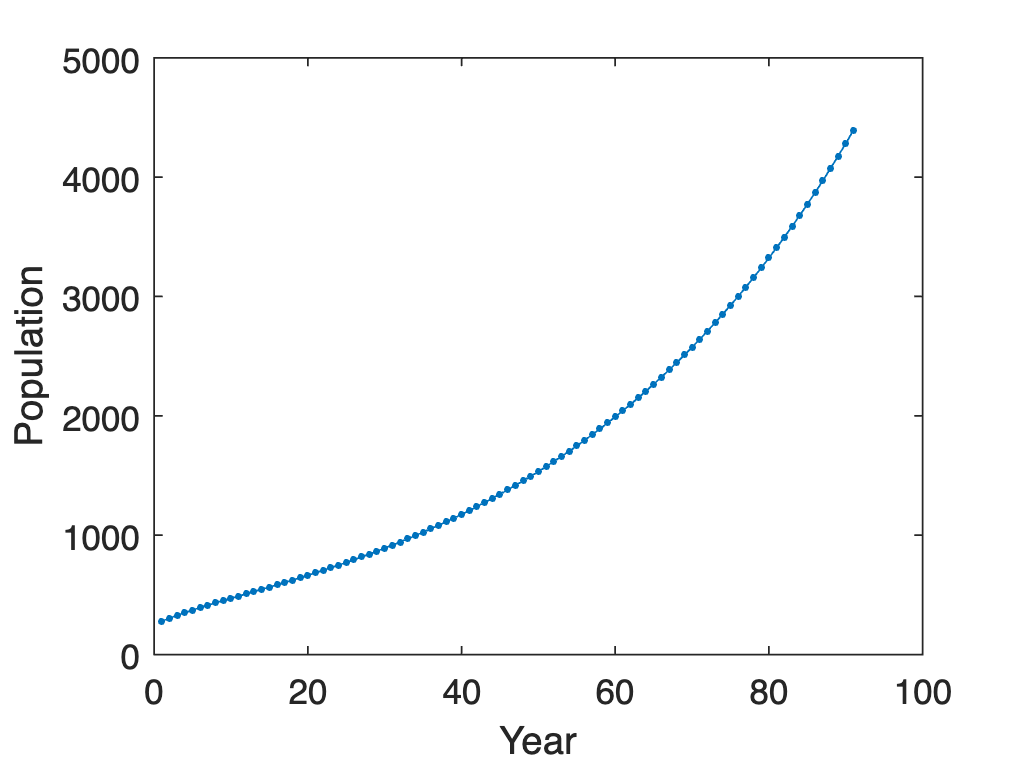

x = [0
    0
    250
    0];
time_range = 91;
N = zeros(1, time_range);
fraction = zeros(4, time_range);
lambda = zeros(1, time_range - 1);
for t = 1: time_range
    x = A * x;
    N(t) = sum(x);
    fraction(:,t) = x / N(t);
end
for t = 1: time_range - 1
    lambda(t) = N(t + 1) / N(t);
end
% plot N
plot(1:time_range, N(1, :), '- .');
xlabel("Year");
ylabel("Population");

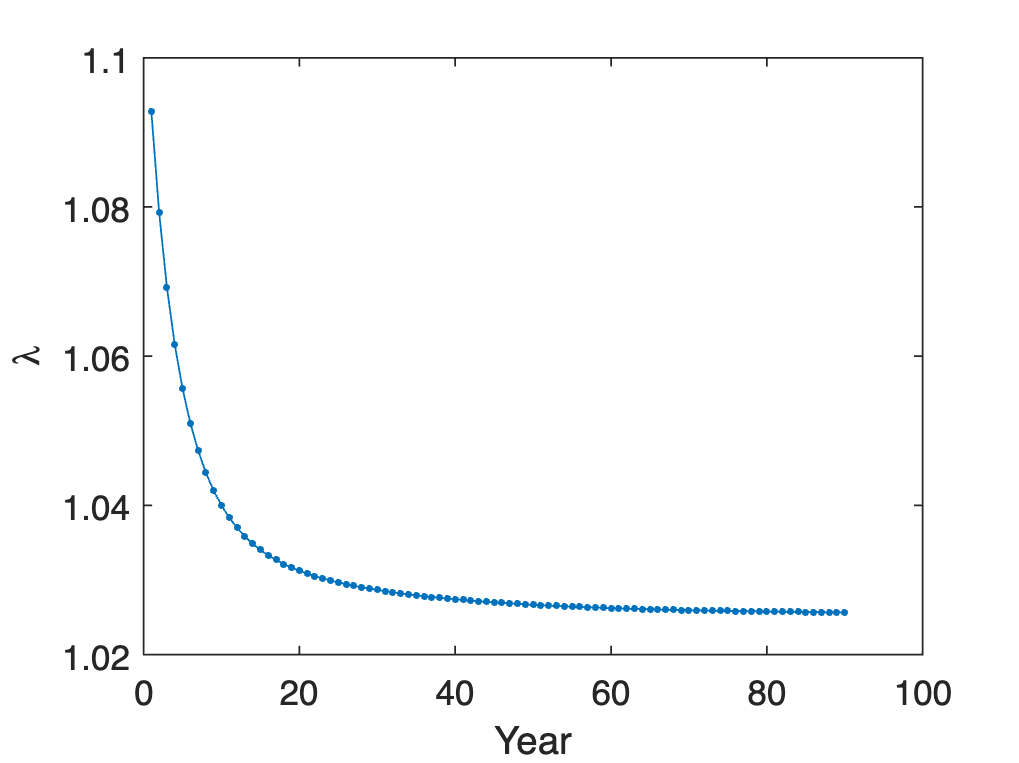

% plot lambda
plot(1:time_range - 1, lambda(1, :), '- .');
xlabel("Year");
ylabel("\lambda");

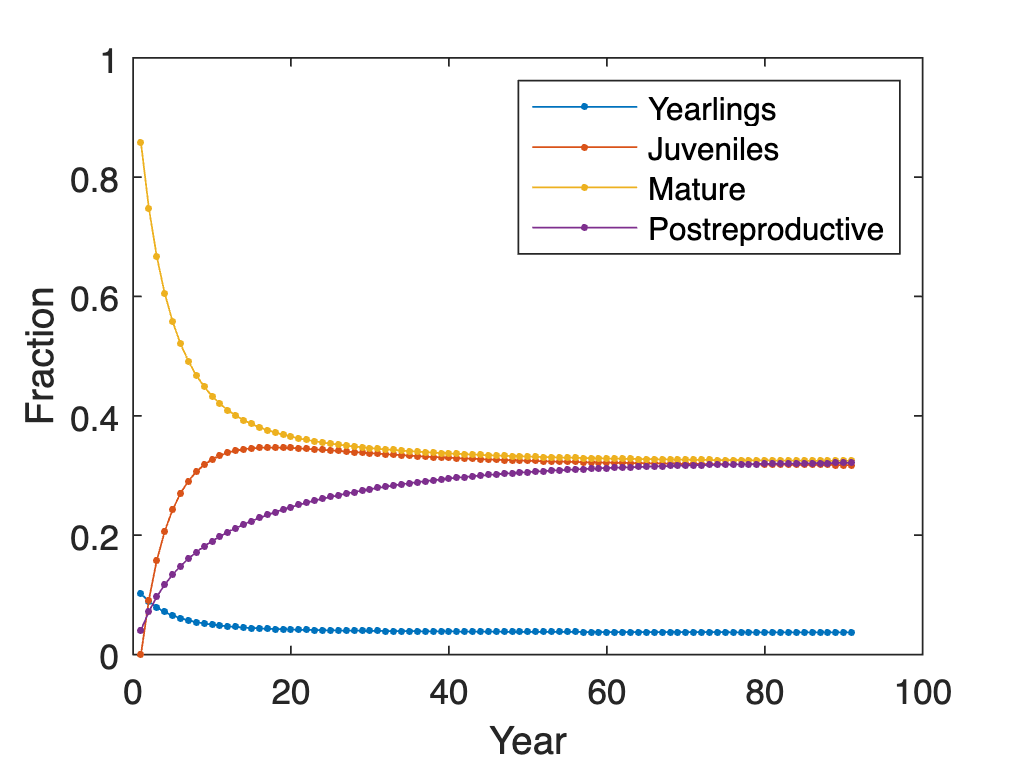

% plot fraction
for i = 1:size(fraction, 1)
    plot(1: time_range, fraction(i, :), '- .');
    hold on
end
legend(["Yearlings", "Juveniles", "Mature", "Postreproductive"]);
xlabel("Year");
ylabel("Fraction");
hold off

`4.`$x_0 =\left\lbrack \begin{array}{cccc}
0 & 0 & 0 & 250
\end{array}\right\rbrack$

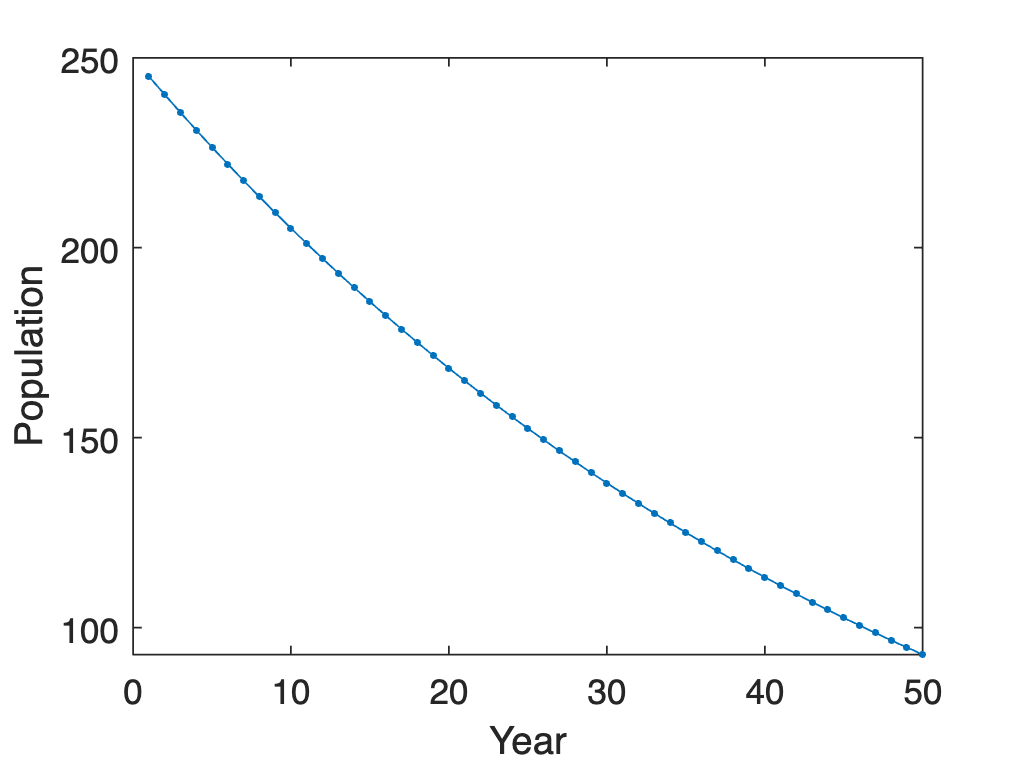

x = [0
    0
    0
    250];
time_range = 50;
N = zeros(1, time_range);
fraction = zeros(4, time_range);
lambda = zeros(1, time_range - 1);
for t = 1: time_range
    x = A * x;
    N(t) = sum(x);
    fraction(:,t) = x / N(t);
end
for t = 1: time_range - 1
    lambda(t) = N(t + 1) / N(t);
end
% plot N
plot(1:time_range, N(1, :), '- .');
xlabel("Year");
ylabel("Population");

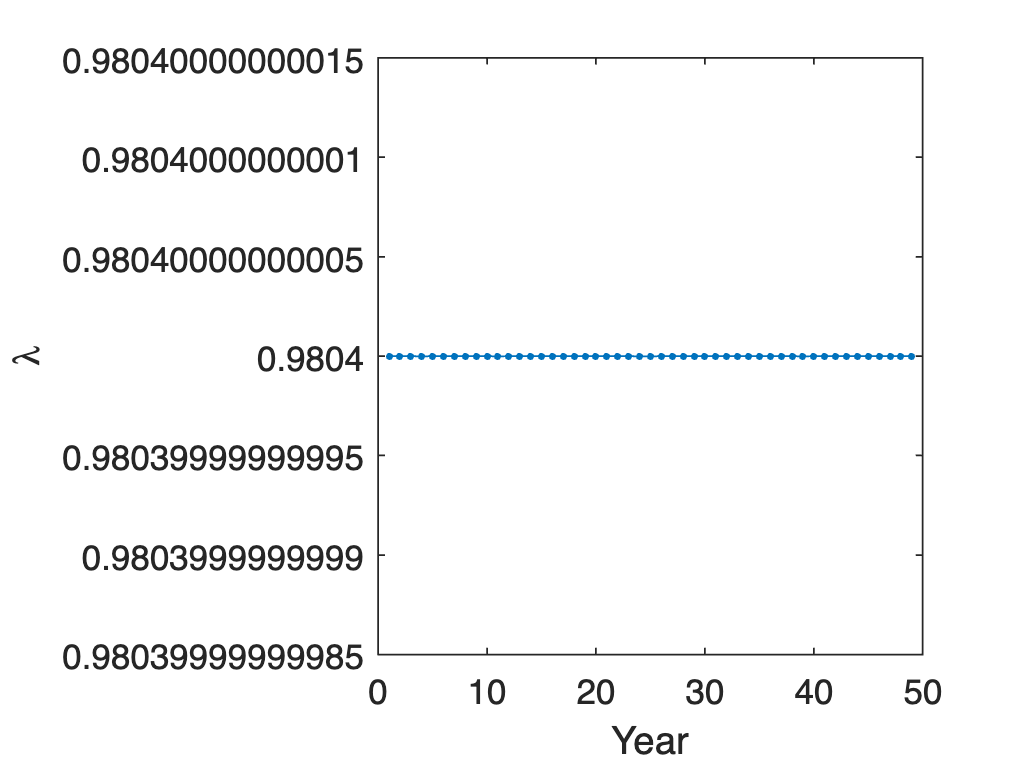

% plot lambda
plot(1:time_range - 1, lambda(1, :), '- .');
xlabel("Year");
ylabel("\lambda");

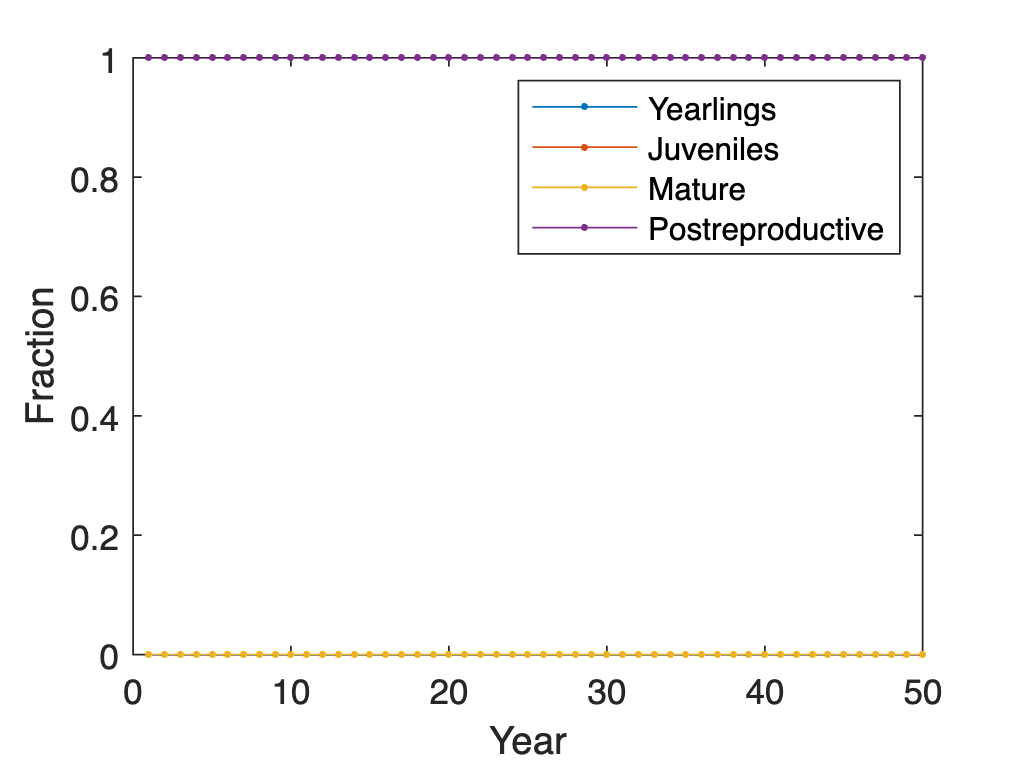

% plot fraction
for i = 1:size(fraction, 1)
    plot(1: time_range, fraction(i, :),'- .');
    hold on
end
legend(["Yearlings", "Juveniles", "Mature", "Postreproductive"]);
xlabel("Year");
ylabel("Fraction");
hold off

`对比分析：`

A, D, V

A =          0    0.0043    0.1132         0
    0.9775    0.9111         0         0
         0    0.0736    0.9534         0
         0         0    0.0452    0.9804


D =     0.9804         0         0         0
         0    1.0254         0         0
         0         0    0.8342         0
         0         0         0    0.0048


V =          0    0.0663   -0.0659    0.6788
         0    0.5672    0.8380   -0.7321
         0    0.5795   -0.5175    0.0568
    1.0000    0.5815    0.1600   -0.0026


`（a）除了只有老年个体的情况，其余三种情况一段时间后均可形成稳定的种群结构，原因如下：`

`但种群中只有老年个体时，`$\vec{n\left(0\right)} =250\vec{w_1 } =250\left\lbrack \begin{array}{c}
0\\
0\\
0\\
1
\end{array}\right\rbrack$`，从而有`$\vec{n\left(1\right)} =250\lambda_1 \vec{w_1 }$`，以此类推，`$\vec{n\left(t\right)} =250\lambda_1^t \vec{w_1 } =\left\lbrack \begin{array}{c}
0\\
0\\
0\\
250\lambda_1^t 
\end{array}\right\rbrack$`，因此种群中始终只有老年个体，且种群数量呈指数下降。而在其余三种情况中，`$\vec{n\left(0\right)}$`关于特征向量的线性组合中均含有`$\vec{w_2 } =\left\lbrack \begin{array}{c}
0\ldotp 0663\\
0\ldotp 5672\\
0\ldotp 5795\\
0\ldotp 5815
\end{array}\right\rbrack$`，因此种群结构最终都会趋于`$\vec{w_2 }$`的分布。`

`（b）Mature阶段是最重要的，因为其与种群出生率直接相关，在一定程度上决定了种群的年增长率`$\lambda$`。`

`Exercise 2.15`

`经测试模拟，每次捕猎Juvenile个体的最大数量为5只；每次捕猎Mature个体的最大数量为3只。`

`验证如下：`

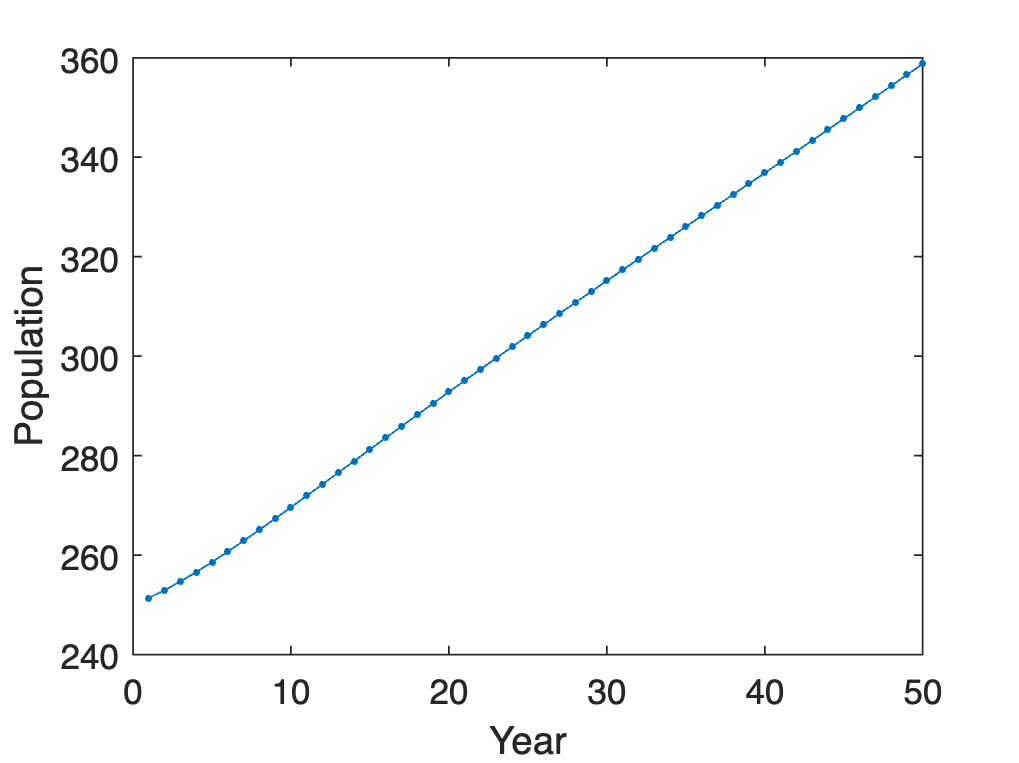

x = 250 * w / sum(w);
h1 = [0
    5
    0
    0];
time_range = 50;
N = zeros(1, time_range);
fraction = zeros(4, time_range);
lambda = zeros(1, time_range - 1);
for t = 1: time_range
    x = A * x - h1;
    N(t) = sum(x);
    fraction(:,t) = x / N(t);
end
for t = 1: time_range - 1
    lambda(t) = N(t + 1) / N(t);
end
% plot N
plot(1:time_range, N(1, :), '- .');
xlabel("Year");
ylabel("Population");

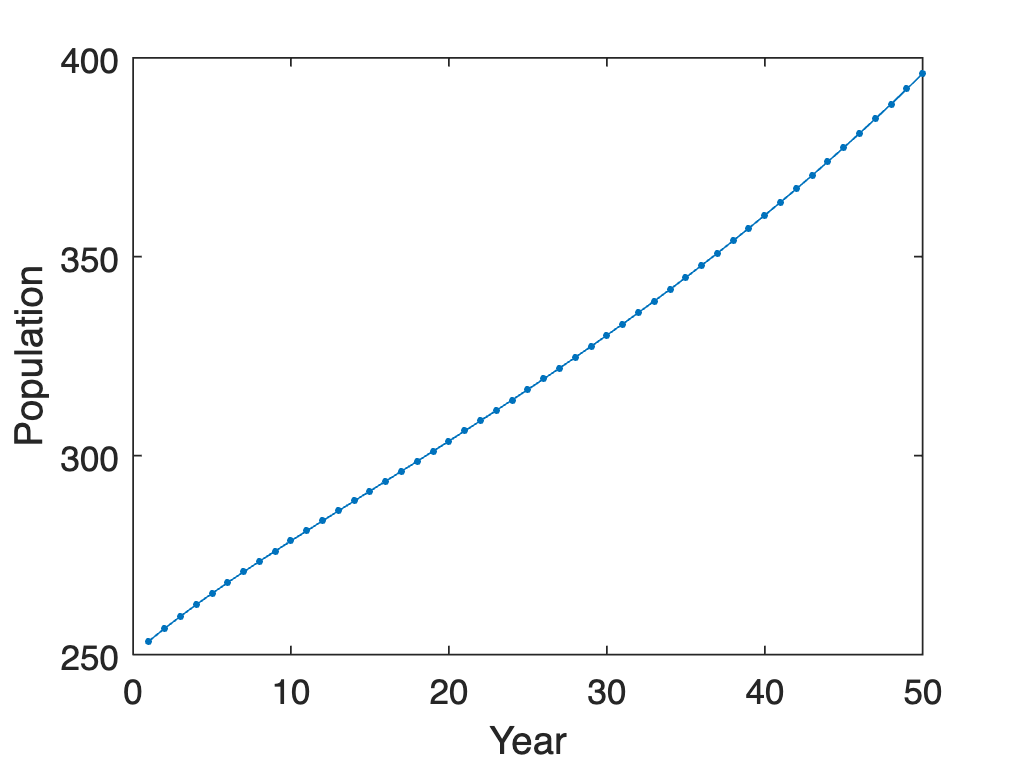

x = 250 * w / sum(w);
h2 = [0
    0
    3
    0];
time_range = 50;
N = zeros(1, time_range);
fraction = zeros(4, time_range);
lambda = zeros(1, time_range - 1);
for t = 1: time_range
    x = A * x - h2;
    N(t) = sum(x);
    fraction(:,t) = x / N(t);
end
for t = 1: time_range - 1
    lambda(t) = N(t + 1) / N(t);
end
% plot N
plot(1:time_range, N(1, :), '- .');
xlabel("Year");
ylabel("Population");

### `Function Complement`

`Exercise 9.3`

function B = rmatrix(A, S, Z)
    B = A + S .* Z;
end